clear;
%close all;

%Parameter define
DC_max = 311;
Ld = 15*1e-3;
Lq = 19*1e-3;
Rs = 0.8975;
Pasi = 0.1764;
Pole_pair = 3;
Omega_m = 104.7; %% Hz
I_max = 10%17.5;

I_max = 10

Id_max = -10 %-0.35*25;

Id_max = -10

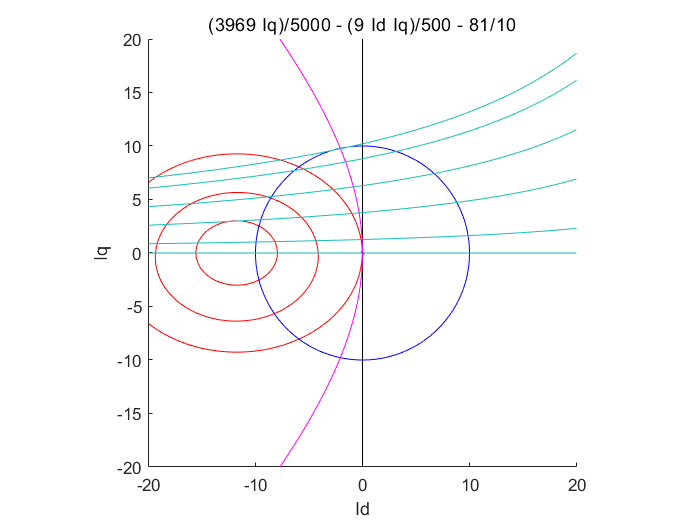

Te = 5;

%Calculate
syms Id Iq;
Omega_e = 1571;
% figure set
figure;
axis equal;
%ezplot(Iq*(Id-Id_max),[-30,30,-30,30]);

hold on;
h = ezplot(Id*Iq,[-20,20,-20,20]);
set(h,'color','k');

hold on;
% plot voltage oval
h = ezplot((-Omega_e*Lq*Iq+Id*Rs).^2+(Omega_e*Ld*Id+Omega_e*Pasi+Iq*Rs).^2 - (DC_max/sqrt(3)).^2,[-20,20,-20,20]);
set(h,'color','r');

hold on;
h = ezplot((-Omega_e*2*Lq*Iq).^2+(Omega_e*2*Ld*Id+Omega_e*2*Pasi).^2 - (DC_max/sqrt(3)).^2,[-20,20,-20,20]);
set(h,'color','r');
Omega_e = 1020;
hold on;
h = ezplot((-Omega_e*Lq*Iq).^2+(Omega_e*Ld*Id+Omega_e*Pasi).^2 - (DC_max/sqrt(3)).^2,[-20,20,-20,20]);
set(h,'color','r');

%Omega_e = 800;
%hold on;
%h = ezplot((-Omega_e*Lq*Iq).^2+(Omega_e*Ld*Id+Omega_e*Pasi).^2 - (DC_max/sqrt(3)).^2,[-20,20,-20,20]);
%set(h,'color','r');

%Omega_e = 750;
%hold on;
%h = ezplot((-Omega_e*Lq*Iq).^2+(Omega_e*Ld*Id+Omega_e*Pasi).^2 - (DC_max/sqrt(3)).^2,[-20,20,-20,20]);
%set(h,'color','r');

% plot current circle
hold on ;
h = ezplot(Id.^2+Iq.^2 - I_max.^2,[-10,10,-10,10]);
set(h,'color','b');



% plot T limit
Te = 0;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-20,20,-20,20]);

Te = 1;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-20,20,-20,20]);

Te = 3;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-20,20,-20,20]);

Te = 5;
hold on;
h = ezplot(2*(Lq-Ld)*Id+sqrt(Pasi.^2+(4*(Lq-Ld).^2)*Iq.^2)-Pasi,[-20,20,-20,20]);
set(h,'color','m');
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-20,20,-20,20]);

Te = 7;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-20,20,-20,20]);

Te = 8.1;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-20,20,-20,20]);

xlim([-20 20])
ylim([-20 20])